# Add cages to regular layout

This guide explains how to add additional cages to a regular cage layout. The code works by adding cages according to a specified *side* of the farm. For simple (i.e. rectangular) cage layouts this means choosing one (or more) of the four orthogonal farm sides. For more complex cage layouts, alternative logic is required.

## Initialise a project and run

Let's just read in the project we have been using so far and seek to extend the cage layout.

projectDir = 'C:\newdepomod_projects\bay_of_fish';
project = Depomod.Project.create(projectDir);
run = project.solidsRuns.first;

A simple plot will remind us of our starting point

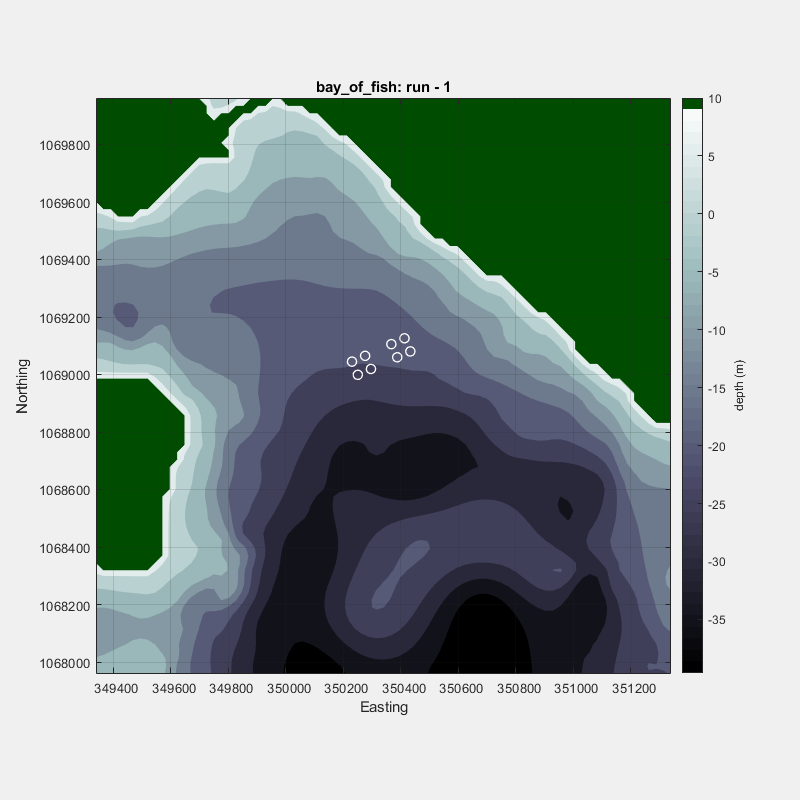

c =   ColorBar (depth (m)) with properties:

    Location: 'eastoutside'
      Limits: [-39.622682675 10]
    FontSize: 9
    Position: [0.852083333333351 0.158125000000073 0.0266666666666667 0.71875]
       Units: 'normalized'

  Show all properties

bool = logical
   1

ans =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 -100 600 600]
       Units: 'points'

  Show all properties

run.plot('impact', 0)

We can also obtain the site layout representation in Matlab.

site = run.cages

site =   2 Site array with properties:

    cageGroups: {[4 Depomod.Layout.Cage.Group]  [4 Depomod.Layout.Cage.Group]}
          path: 'C:\newdepomod_projects\bay_of_fish\depomod\cages\bay_of_fish-1.depomodcagesxml'

## Layout corners and sides

We can use some simple geometry to help us navigate the cage layout and add new cages. Some useful features of the toolbox are those which identify the corners and bounding sides of the cage layout (i.e. the "bounding box").

The site corners can be identified as a simple 4 point list of coordinates.

site.corners

ans =           350421.067926405          1069147.01907142
          350209.304110391          1069052.73007305
          350242.593108762          1068977.96625704
          350454.356924777          1069072.25525541


We can plot these, as follows:

run.plot('impact',0)

c =   ColorBar (depth (m)) with properties:

    Location: 'eastoutside'
      Limits: [-39.622682675 10]
    FontSize: 9
    Position: [0.852083333333351 0.158125000000073 0.0266666666666667 0.71875]
       Units: 'normalized'

  Show all properties

bool = logical
   1

ans =   Figure (2) with properties:

      Number: 2
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 -100 600 600]
       Units: 'points'

  Show all properties

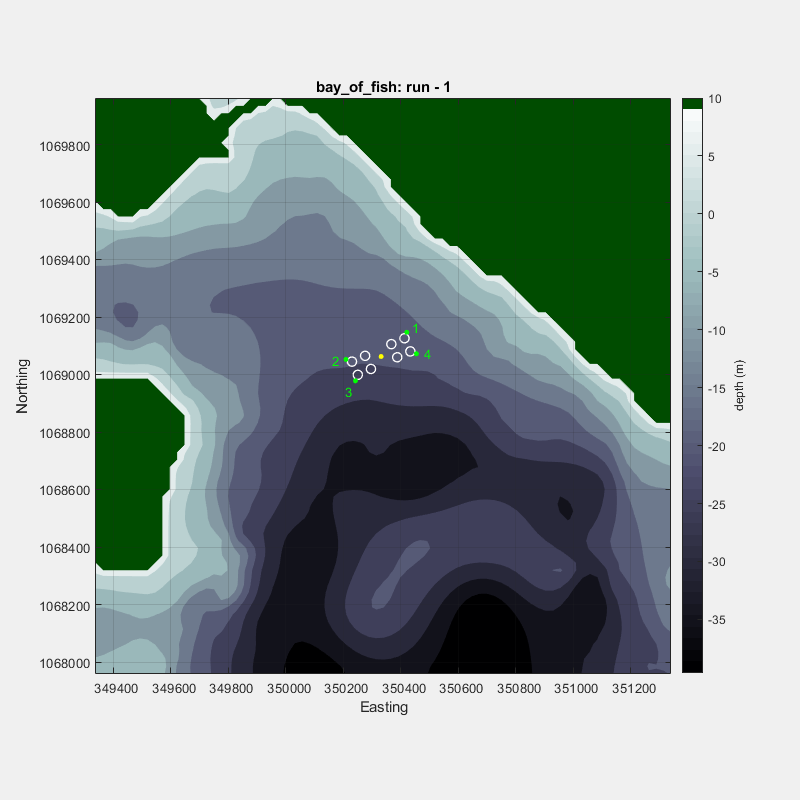

site.boundingBox.plotCorners

Likewise, we can identify the individual sides of the site bounding box. The site bounding box object has 4 objects representing the sides.

run.plot('impact',0)

c =   ColorBar with properties:

    Location: 'eastoutside'
      Limits: [-39.622682675 10]
    FontSize: 9
    Position: [0.788690476190489 0.10952380952381 0.0380952380952381 0.816666666666667]
       Units: 'normalized'

  Show all properties

bool = logical
   1

ans =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 -100 600 600]
       Units: 'points'

  Show all properties

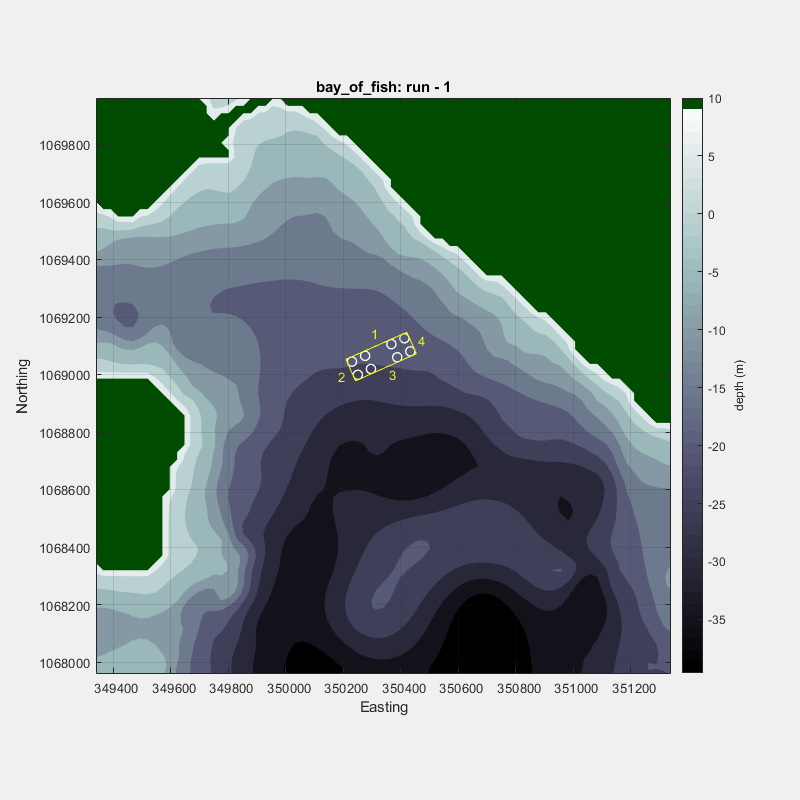

site.boundingBox.plotSides

For both the corners and the sides, the plotted labels represent the indexes used to represent each respective corner and side in the Matlab objects.

The bounding box object on the site layout object includes a range of useful functionality.

## Adding cages along a specific side of a site

We can use some of the functionality of the toolbox to help us add cages along a particular side of the farm. Suppose we decide we want to add cages along the southern edge of this farm, i.e. side #3. The following code gives a general pattern for achieving this.

side      = 3;           % set the desired farm side
nNewCages = 5;           % set the number of new cages wanted

% identify the cage spacing employed in this layout (assumes regular grid)
spacing = site.cageSpacing;
spacing = round(spacing(1))

spacing =     50


site = run.cages;         % get site object
site.consolidateCages;    % consolidate cage groups in to one cage group for simplicity

% retrieve the outward pointing bearing relative to side #3
bearing = site.boundingBox.Sides(side).OutwardBearing

bearing =           155.998719034106

unit_n  = cosd(bearing) % unit vector component

unit_n =         -0.913536363973687

unit_e  = sind(bearing) % unit vector component

unit_e =          0.406757067176139


% identify the cages which site along side #3
[c,i]=site.boundingBox.Sides(side).cages;
nCages = numel(c) % count them

nCages =      4


% add number of cages specified
for n = 1:nNewCages
    % cycle past the existing cages along the edge under consideration and add new cages
    
    ni = mod(n, nCages);
    f  = ceil(n/nCages);
    
    if ni == 0
        ni = nCages;
    end
    
    % get the adjacent cage
    cage_e = c{ni}.x;
    cage_n = c{ni}.y;
    
    % calculate coordinates for the new cage
    new_cage_e = cage_e + unit_e*spacing*f;
    new_cage_n = cage_n + unit_n*spacing*f;
    
    % add new cage
    site.cageGroups{1}.cages{end+1} = site.cageGroups{1}.cages{end};
    site.cageGroups{1}.cages{end}.x = new_cage_e;
    site.cageGroups{1}.cages{end}.y = new_cage_n;
end

% IMPORTANT - ensure all cages set to correct (uniformly distributed) proportion of discharge
for c = 1:site.sizeCages
    site.cageGroups{1}.cages{c}.proportion = 1/site.sizeCages;
end

% assign new cage layout to run object
run.cages = site;

Plot the new cages to check we have what we want

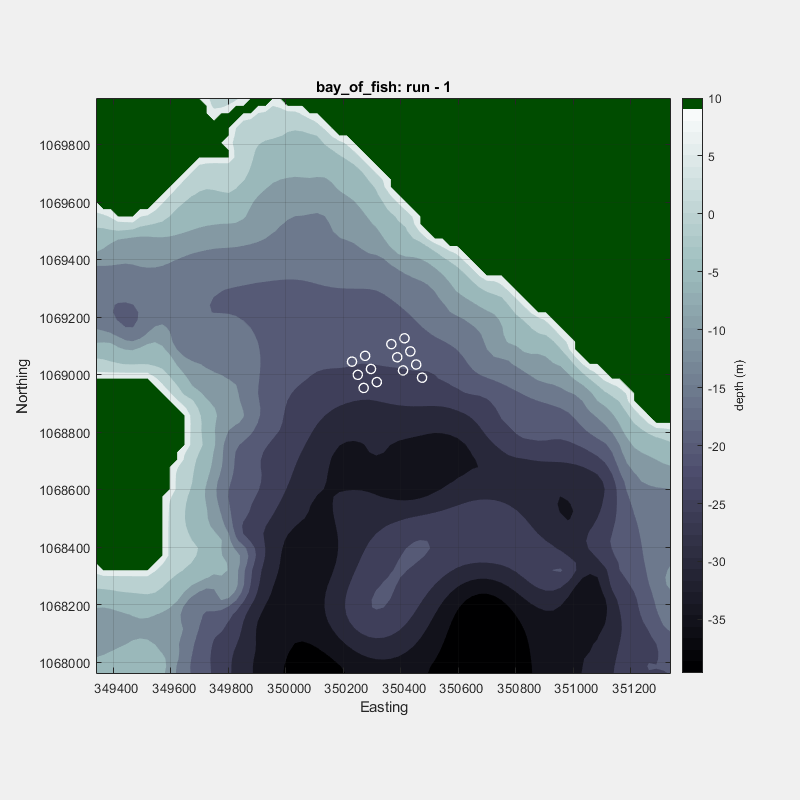

c =   ColorBar (depth (m)) with properties:

    Location: 'eastoutside'
      Limits: [-39.622682675 10]
    FontSize: 9
    Position: [0.852083333333351 0.158125000000073 0.0266666666666667 0.71875]
       Units: 'normalized'

  Show all properties

bool = logical
   1

ans =   Figure (4) with properties:

      Number: 4
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 -100 600 600]
       Units: 'points'

  Show all properties

run.plot('impact',0)

Okay, that seems fine. The same principle can be used to add cages to the other sides. 

## Writing to file

As always, these changes have only been made with respect to the Matlab representation held in memory. To have effect in the model they need to be written back to file.

run.cages.toFile

## Limitations and best practice

This procedure assumes a regular grid layout and seeks to add new cages according to that regular layout. Arbitrary or more complicated layouts may cause issues. Another thing to be careful of is incrementally adding cages. In the case above we added 5 cages along a farm length which was 4 cages. This meant we started a whole new row which included just one cage. This skews the bounding box of the site layout to a non-regular angle, i.e.:

run.plot('impact',0);

c =   ColorBar (depth (m)) with properties:

    Location: 'eastoutside'
      Limits: [-39.622682675 10]
    FontSize: 9
    Position: [0.852083333333351 0.158125000000073 0.0266666666666667 0.71875]
       Units: 'normalized'

  Show all properties

bool = logical
   1

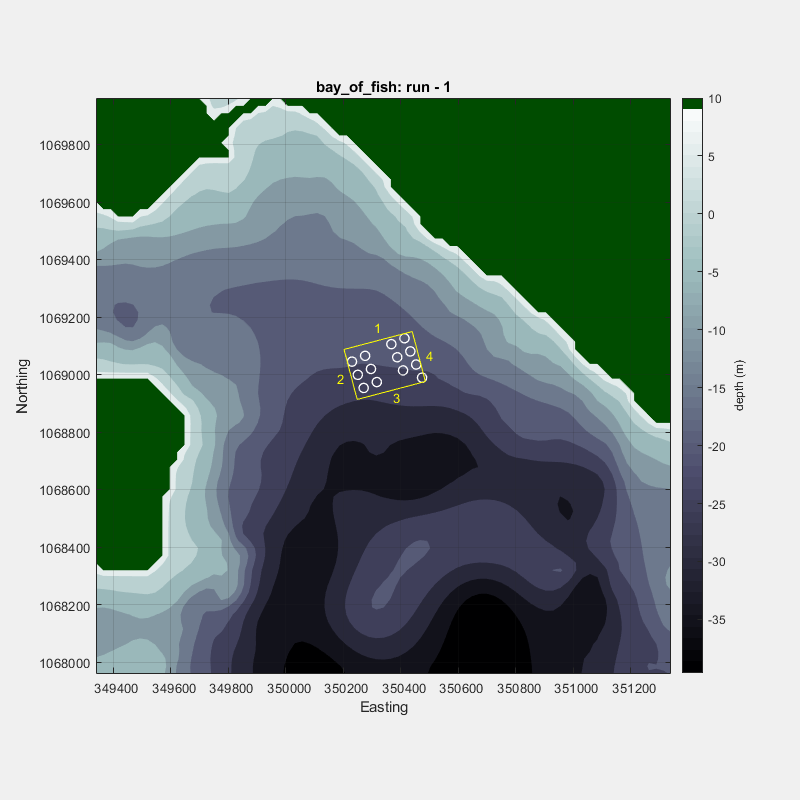

run.cages.boundingBox.plotSides

If we were to add cages again, from this new starting point, the additional cages would be oriented according to this new bounding box and it would probably result in cages being either organised in a non-regular way or even cages being unacceptably coincident in space. A better approach for adding to *this* layout would be to use the same starting point (i.e. the original 8 cages) and add the full new required number of cages from there.